## Cast Binary Point Analysis

Analyze data type conversion, i.e. cast


$$\textrm{Vy}=\textrm{Va}$$


where the types of Vu and Vy are the following binary-point scaled fixed-point data types.

ntu = numerictype(1,16,10);
fprintf('ntu = %s\n',ntu.tostring);

ntu = numerictype(1,16,10)


ntu = fixed.extractNumericType(ntu)

ntu =

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 16
        FractionLength: 10


nty = numerictype(1,8,4);
fprintf('nty = %s\n',nty.tostring);

nty = numerictype(1,8,4)


nty = fixed.extractNumericType(nty)

nty =

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 8
        FractionLength: 4


assert(~ntu.isslopebiasscaled && ~nty.isslopebiasscaled, "Only binary-point fixed-point cases are analyzed.")

### **Extreme values of input u**

uUp = upperbound(ntu);
uLo = lowerbound(ntu);
uZero = fi(0,ntu);
uMinPos = fixed.internal.type.minPosFiniteRepresentableVal(ntu);
if isempty(uMinPos)
    uMinPos = uUp;
end
uMaxNeg = fixed.internal.type.maxNegFiniteRepresentableVal(ntu);
if isempty(uMaxNeg)
    uMaxNeg = uLo;
end
uVec = fliplr(fixed.internal.math.unique([uUp, uMinPos, uZero, uMaxNeg, uLo]));
dispSetOfValues(uVec);


Data type is numerictype(1,16,10)

   Real World    Notation: Binary Point
     Value         
 31.9990234375 =  011111.1111111111
  0.0009765625 =  000000.0000000001
       0       =  000000.0000000000
 -0.0009765625 =  111111.1111111111
      -32      =  100000.0000000000


### **Extreme values of output y**

yUp = upperbound(nty);
yLo = lowerbound(nty);
yZero = fi(0,nty);
yMinPos = fixed.internal.type.minPosFiniteRepresentableVal(nty);
if isempty(yMinPos)
    yMinPos = yUp;
end
yMaxNeg = fixed.internal.type.maxNegFiniteRepresentableVal(nty);
if isempty(yMaxNeg)
    yMaxNeg = yLo;
end
yVec = fliplr(fixed.internal.math.unique([yUp, yMinPos, yZero, yMaxNeg, yLo]));
dispSetOfValues(yVec);


Data type is numerictype(1,8,4)

 Real World   Notation: Binary Point
    Value       
   7.9375   =  0111.1111
   0.0625   =  0000.0001
      0     =  0000.0000
   -0.0625  =  1111.1111
     -8     =  1000.0000


## Overflow Handling

Overflows can be handled in either of two ways.

The first is to saturate out of ranges values on the right side to the maximum representable output value and to saturate out of ranges values on the left side to the minimum representable output value.

The second is to wrap around like on the hands of a clock.

Depending on rounding  mode the number of overflows possible and which specific values overflow can be slightly different.

                  nRepInput    nInputOverflow    ratioRepInputOverflow
                  _________    ______________    _____________________
    Floor           65536          49152                        0.75  
    Nearest         65536          49152                        0.75  
    Zero            65536          49089           0.749038696289062  
    Ceiling         65536          49152                        0.75  
    Round           65536          49153           0.750015258789062  
    Convergent      65536          49152                        0.75  


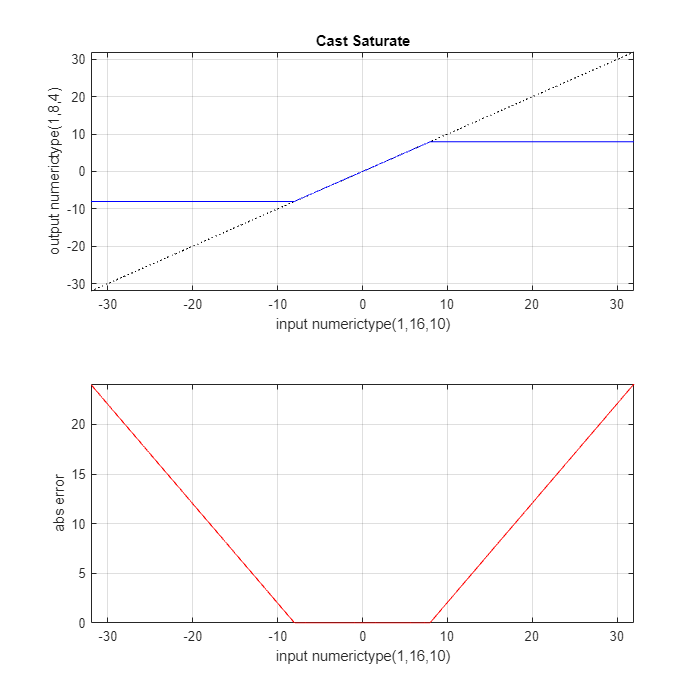

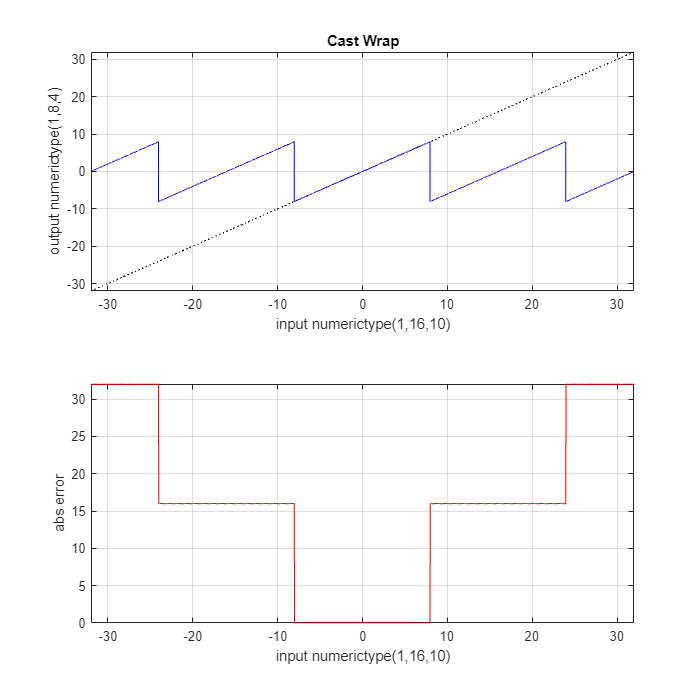

rndModes = {'Floor','Nearest','Zero','Ceiling','Round','Convergent'};

rOverflow = struct();
for i=1:numel(rndModes)
    rCur = castStats(ntu,nty,rndModes{i});
    curCount = rCur.overflowCountTot;
    if curCount > 0
        canOverflow = true;
    end
    rOverflow(i).nRepInput = rCur.cardinalityTot;
    rOverflow(i).nInputOverflow = rCur.overflowCountTot;
    rOverflow(i).ratioRepInputOverflow = rCur.overflowRatioTot;
end
tOverflowInfo = struct2table(rOverflow,'RowNames',rndModes);

%canOverflow = (uLo < yLo) || (yUp < uUp);
if ~canOverflow
    disp('No chance of overflow for this cast.')
else
    disp(tOverflowInfo)
    yLike = fi([],nty);
    wlu = ntu.WordLength;
    wlMax = 17;
    nMax = min( 2^wlMax - 17, 2^wlu );
    uTest = linspace(double(uLo),double(uUp),nMax);
    uTest = fi(uTest,ntu);
    if wlu > wlMax
        ds = fixed.DataSpecification(ntu);
        dg = fixed.DataGenerator('DataSpecifications', {ds});
        vRich = dg.outputAllData('array');
        uTest = fixed.internal.math.unique([uTest, vRich]);
    end
    r = exFixptCast(uTest,yLike);

    if yLo < 0
        narrowLo = nty.Slope * -4;
        narrowHi = nty.Slope *  4;
    else
        narrowLo = nty.Slope *  0;
        narrowHi = nty.Slope *  8;
    end

    ii = narrowLo <= uTest & uTest <= narrowHi;

    fns = {'ySatNearTieInf','yWrapNearTieInf'};
    titleSet = {'Saturate','Wrap'};
    nf = numel(fns);
    for i = 1:nf
        fn = fns{i};
        h = figure();

        subplot(2,1,1)
        plot(uTest,uTest,'k:',uTest,r.(fn),'b')
        xlabel(sprintf('input %s',ntu.tostring))
        ylabel(sprintf('output %s',nty.tostring))
        title(['Cast ',titleSet{i}])
        axis tight
        grid on

        absErr = abs(double(r.(fn)) - double(uTest));
        subplot(2,1,2)
        plot(uTest,absErr,'r')
        xlabel(sprintf('input %s',ntu.tostring))
        ylabel('abs error')
        axis tight
        grid on
        xy = h.Position;
        xy(3:4) = [700, 700];
        h.Position = xy;
    end
end

## Nearest Rounding (nearest with ties toward +Inf)

With nearest rounding, rounding error will be in the range (-0.5, 0.5] bits. In real-world values, the rounding error is (-0.5*SlopeY, 0.5*SlopeY].

In simple terms, the absolute rounding error is always half a bit or less.

Exact ties will round up, i.e. in the direction of +Inf.

For fixed-point to fixed-point casts, a big advantage of nearest rounding is that among rounding methods that give half a bit or less of error, nearest requires the smallest and fastest code. Rounding to Floor is even leaner, but it doubles the worst case rounding error. Compare code examples below.

nearestRoundingExamples(ntu,nty);

Below mid-point, round down

         Type           Real World    Notation: Binary Point
                           Value        
 numerictype(1,16,10)  7.9052734375 =       000111.1110011111
  numerictype(1,16,4)      7.875    = 000000000111.1110      
  numerictype(1,8,4)       7.875    =         0111.1110      

At mid-point, round up

         Type          Real World   Notation: Binary Point
                          Value       
 numerictype(1,16,10)    7.90625  =       000111.1110100000
  numerictype(1,16,4)    7.9375   = 000000000111.1111      
  numerictype(1,8,4)     7.9375   =         0111.1111      

Above mid-point, round up

         Type           Real World    Notation: Binary Point
                           Value        
 numerictype(1,16,10)  7.9072265625 =       000111.1110100001
  numerictype(1,16,4)     7.9375    = 000000000111.1111      
  numerictype(1,8,4)      7.9375    =         0111.1111      


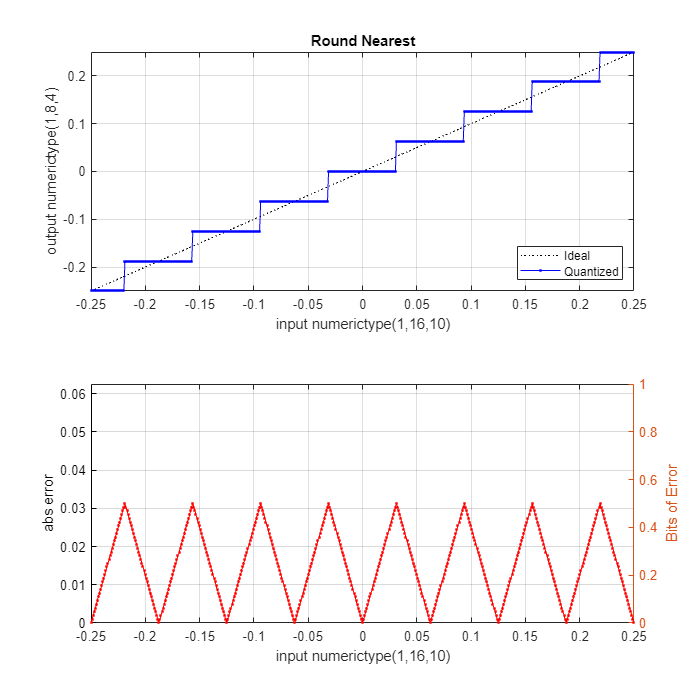


fn = 'ySatNearTieInf';
h = figure();

subplot(2,1,1)
plot(uTest(ii),uTest(ii),'k:',uTest(ii),r.(fn)(ii),'b.-')
xlabel(sprintf('input %s',ntu.tostring))
ylabel(sprintf('output %s',nty.tostring))
title('Round Nearest')
legend({ ...
    'Ideal'
    'Quantized'},'location','southeast');
axis tight
grid on

err = (double(r.(fn)) - double(uTest));
absErr = abs(err);
subplot(2,1,2)
plot(uTest(ii),absErr(ii),'r.-')
xlabel(sprintf('input %s',ntu.tostring))
ylabel('abs error')
axis tight
grid on
yl = ylim;
yl(1) = min(yl(1),0);
yl(2) = max(yl(2),nty.Slope);
ylim(yl);
yl2 = (yl)/nty.Slope;
yyaxis right
ylim(yl2)
ylabel('Bits of Error')
yyaxis left
xy = h.Position;
xy(3:4) = [700, 700];
h.Position = xy;

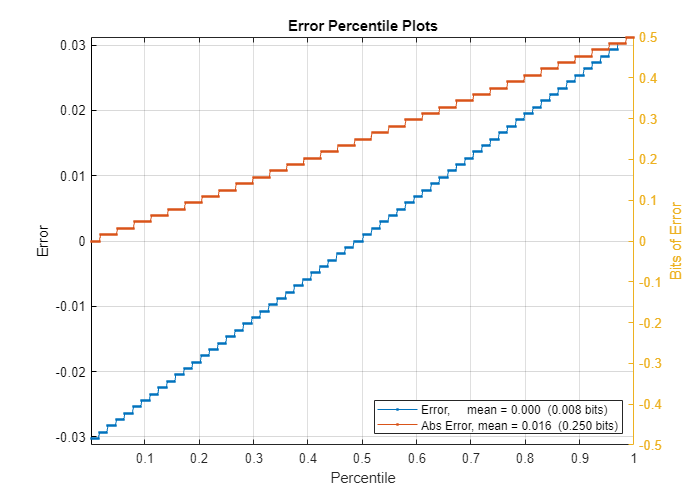

utilPlotErrorPercentile(err(ii),nty);

## Convergent Rounding (nearest with ties to even)

Convergent rounding is like nearest rounding, except ties are rounded to the nearest even output. Even means the last bit of the output is 0.

With convergent rounding, rounding error will be in the range [-0.5, 0.5] bits. In real-world values, the rounding error is [-0.5*SlopeY, 0.5*SlopeY].

An advantage of Convergent over Nearest is that Convergent will have near zero average rounding error (under mild assumption regarding input distribution). If the input is feed to calculations that accumulate errors such as integration, then Convergent is least likely to have significant error drift build up. If the downstream operations do not accumulate or there are corrections from an outer feedback loop, then average error may not be of importance. 

convergentRoundingExamples(ntu,nty)

At mid-point, round to even

         Type          Real World   Notation: Binary Point
                          Value       
 numerictype(1,16,10)    7.84375  =       000111.1101100000
  numerictype(1,16,4)     7.875   = 000000000111.1110      
  numerictype(1,8,4)      7.875   =         0111.1110      

At mid-point, round to even

         Type          Real World   Notation: Binary Point
                          Value       
 numerictype(1,16,10)    7.90625  =       000111.1110100000
  numerictype(1,16,4)     7.875   = 000000000111.1110      
  numerictype(1,8,4)      7.875   =         0111.1110      

Below mid-point, round down

         Type           Real World    Notation: Binary Point
                           Value        
 numerictype(1,16,10)  7.9052734375 =       000111.1110011111
  numerictype(1,16,4)      7.875    = 000000000111.1110      
  numerictype(1,8,4)       7.875    =         0111.1110      

Above mid-point, round up

         Type           Real World    N

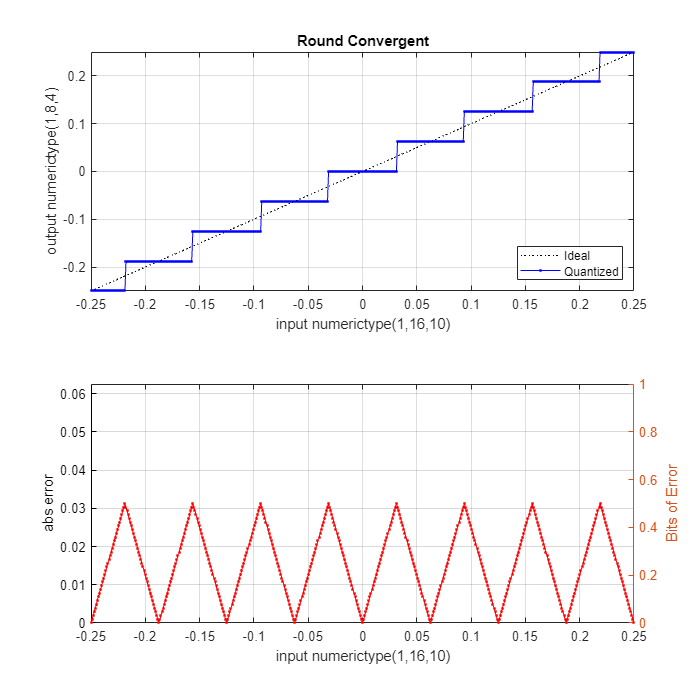

fn = 'ySatNearTieEven';
h = figure();

subplot(2,1,1)
plot(uTest(ii),uTest(ii),'k:',uTest(ii),r.(fn)(ii),'b.-')
xlabel(sprintf('input %s',ntu.tostring))
ylabel(sprintf('output %s',nty.tostring))
title('Round Convergent')
legend({ ...
    'Ideal'
    'Quantized'},'location','southeast');
axis tight
grid on

err = (double(r.(fn)) - double(uTest));
absErr = abs(err);
subplot(2,1,2)
plot(uTest(ii),absErr(ii),'r.-')
xlabel(sprintf('input %s',ntu.tostring))
ylabel('abs error')
axis tight
grid on
yl = ylim;
yl(1) = min(yl(1),0);
yl(2) = max(yl(2),nty.Slope);
ylim(yl);
yl2 = (yl)/nty.Slope;
yyaxis right
ylim(yl2)
ylabel('Bits of Error')
yyaxis left
xy = h.Position;
xy(3:4) = [700, 700];
h.Position = xy;

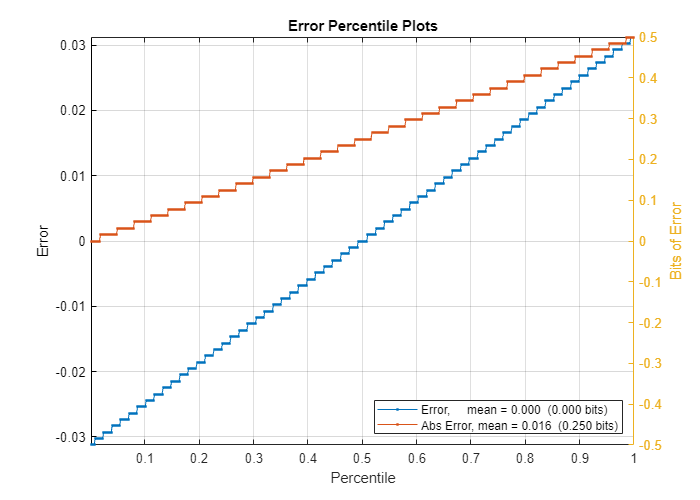

utilPlotErrorPercentile(err(ii),nty);

## Floor Rounding

With floor rounding, rounding error will be in the range (-1, 0] bits. In real-world values, the rounding error is (-SlopeY, 0].

In simple terms, the absolute rounding error is always less than one bit.

For fixed-point to fixed-point casts, a big advantage of floor rounding is that it requires the smallest and fastest code of all the rounding methods. Compare code examples below.

floorRoundingExamples(ntu,nty)

Everything rounds down

         Type           Real World    Notation: Binary Point
                           Value        
 numerictype(1,16,10)  7.8759765625 =       000111.1110000001
  numerictype(1,16,4)      7.875    = 000000000111.1110      
  numerictype(1,8,4)       7.875    =         0111.1110      

Everything rounds down

         Type           Real World    Notation: Binary Point
                           Value        
 numerictype(1,16,10)  7.9365234375 =       000111.1110111111
  numerictype(1,16,4)      7.875    = 000000000111.1110      
  numerictype(1,8,4)       7.875    =         0111.1110      


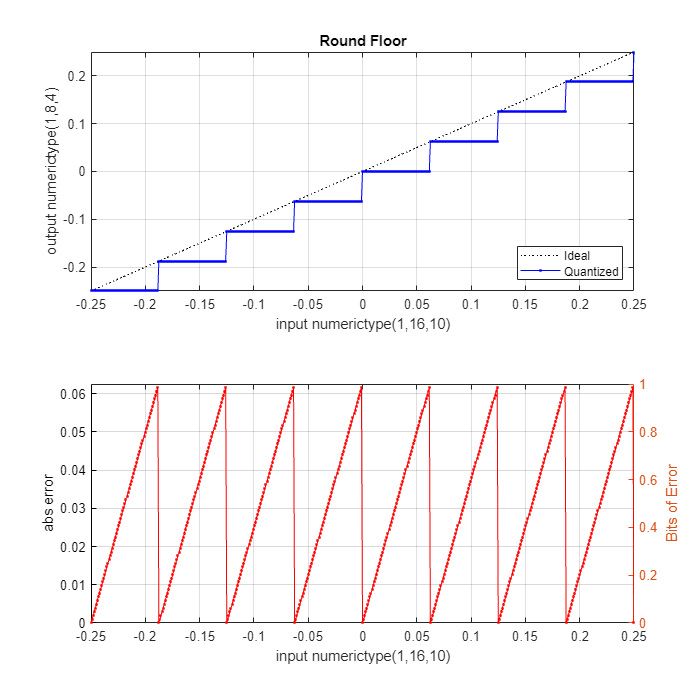

fn = 'ySatFloor';
h = figure();

subplot(2,1,1)
plot(uTest(ii),uTest(ii),'k:',uTest(ii),r.(fn)(ii),'b.-')
xlabel(sprintf('input %s',ntu.tostring))
ylabel(sprintf('output %s',nty.tostring))
title('Round Floor')
legend({ ...
    'Ideal'
    'Quantized'},'location','southeast');
axis tight
grid on

err = (double(r.(fn)) - double(uTest));
absErr = abs(err);
subplot(2,1,2)
plot(uTest(ii),absErr(ii),'r.-')
xlabel(sprintf('input %s',ntu.tostring))
ylabel('abs error')
axis tight
grid on
yl = ylim;
yl(1) = min(yl(1),0);
yl(2) = max(yl(2),nty.Slope);
ylim(yl);
yl2 = (yl)/nty.Slope;
yyaxis right
ylim(yl2)
ylabel('Bits of Error')
yyaxis left
xy = h.Position;
xy(3:4) = [700, 700];
h.Position = xy;

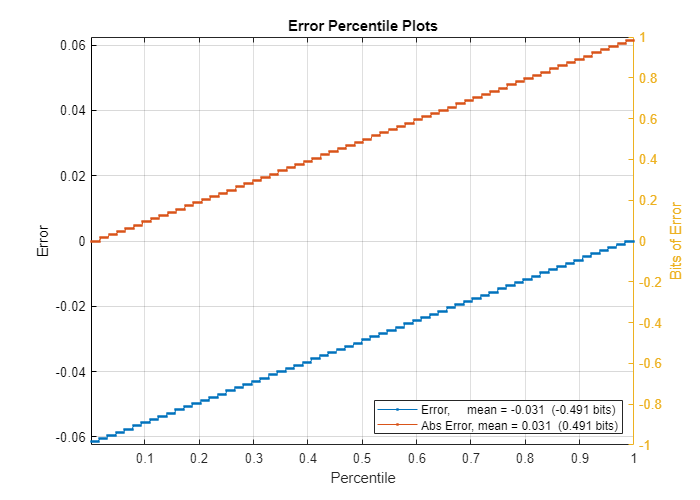

utilPlotErrorPercentile(err(ii),nty);

## Ceiling Rounding

With ceiling rounding, rounding error will be in the range [0, 1) bits. In real-world values, the rounding error is [0, SlopeY).

In simple terms, the absolute rounding error is always less than one bit.

Ceiling rounding is rarely used. It is costlier than Floor without numerical advantages. It is mainly used in specialized applications like interval analysis.

ceilRoundingExamples(ntu,nty)

Everything rounds up

         Type           Real World    Notation: Binary Point
                           Value        
 numerictype(1,16,10)  7.8759765625 =       000111.1110000001
  numerictype(1,16,4)     7.9375    = 000000000111.1111      
  numerictype(1,8,4)      7.9375    =         0111.1111      

Everything rounds up

         Type           Real World    Notation: Binary Point
                           Value        
 numerictype(1,16,10)  7.9365234375 =       000111.1110111111
  numerictype(1,16,4)     7.9375    = 000000000111.1111      
  numerictype(1,8,4)      7.9375    =         0111.1111      


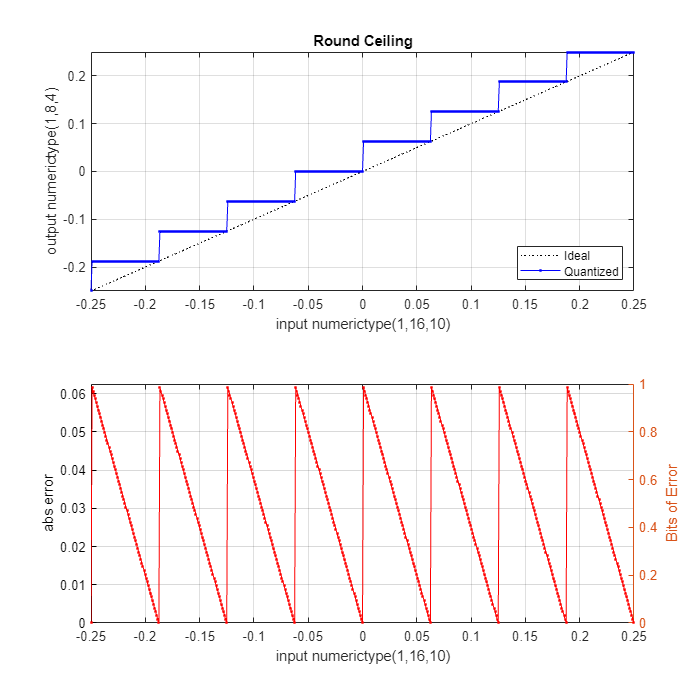

fn = 'ySatCeil';
h = figure();

subplot(2,1,1)
plot(uTest(ii),uTest(ii),'k:',uTest(ii),r.(fn)(ii),'b.-')
xlabel(sprintf('input %s',ntu.tostring))
ylabel(sprintf('output %s',nty.tostring))
title('Round Ceiling')
legend({ ...
    'Ideal'
    'Quantized'},'location','southeast');
axis tight
grid on

err = (double(r.(fn)) - double(uTest));
absErr = abs(err);
subplot(2,1,2)
plot(uTest(ii),absErr(ii),'r.-')
xlabel(sprintf('input %s',ntu.tostring))
ylabel('abs error')
axis tight
grid on
yl = ylim;
yl(1) = min(yl(1),0);
yl(2) = max(yl(2),nty.Slope);
ylim(yl);
yl2 = (yl)/nty.Slope;
yyaxis right
ylim(yl2)
ylabel('Bits of Error')
yyaxis left
xy = h.Position;
xy(3:4) = [700, 700];
h.Position = xy;

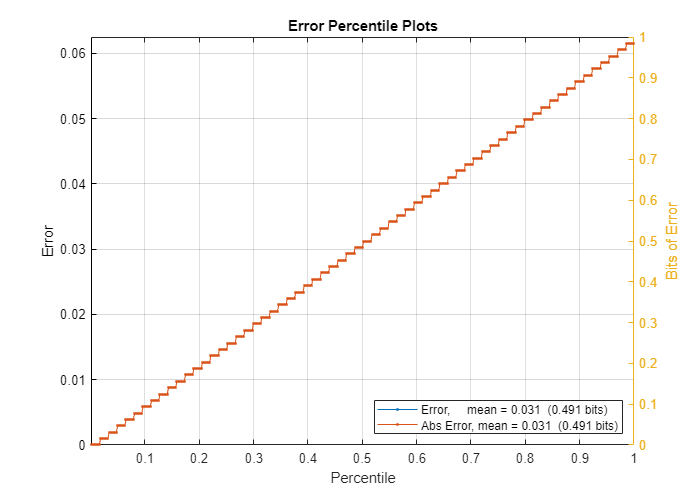

utilPlotErrorPercentile(err(ii),nty);

## Zero Rounding

With zero rounding, rounding error will be in the range (-1, 1) bits. In real-world values, the rounding error is (-SlopeY, SlopeY).

In simple terms, the absolute rounding error is always less than one bit.

For fixed-point to fixed-point casts, zero rounding is rarely used because it is costlier than Floor and does not have numerical advantages.

For floating-point to fixed-point casts, zero rounding is widely used. The C standard mandates that rounding from floating-point to integer will be round to zero. This gives a big efficiency advantage to zero rounding in floating-point to integer and fixed-point types.

For fixed-point division, zero rounding is also often advantageous. The C99 standard mandates that signed integer division must  round toward zero.  (Note, for unsigned round to Floor and Zero are identical.)

zeroRoundingExamples(ntu,nty)

Negatives rounds up

         Type            Real World    Notation: Binary Point
                           Value         
 numerictype(1,16,10)  -0.1240234375 =       111111.1110000001
  numerictype(1,16,4)     -0.0625    = 111111111111.1111      
  numerictype(1,8,4)      -0.0625    =         1111.1111      

Negatives rounds up

         Type            Real World    Notation: Binary Point
                           Value         
 numerictype(1,16,10)  -0.0634765625 =       111111.1110111111
  numerictype(1,16,4)     -0.0625    = 111111111111.1111      
  numerictype(1,8,4)      -0.0625    =         1111.1111      

Positives round down

         Type           Real World    Notation: Binary Point
                           Value        
 numerictype(1,16,10)  0.0634765625 =       000000.0001000001
  numerictype(1,16,4)     0.0625    = 000000000000.0001      
  numerictype(1,8,4)      0.0625    =         0000.0001      

Positives round down

         Type           Real World   

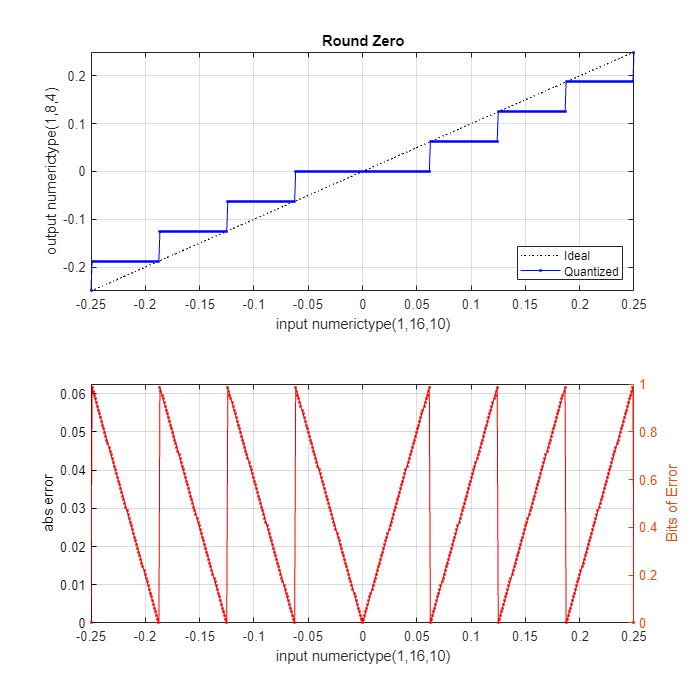

fn = 'ySatZero';
h = figure();

subplot(2,1,1)
plot(uTest(ii),uTest(ii),'k:',uTest(ii),r.(fn)(ii),'b.-')
xlabel(sprintf('input %s',ntu.tostring))
ylabel(sprintf('output %s',nty.tostring))
title('Round Zero')
legend({ ...
    'Ideal'
    'Quantized'},'location','southeast');
axis tight
grid on

err = (double(r.(fn)) - double(uTest));
absErr = abs(err);
subplot(2,1,2)
plot(uTest(ii),absErr(ii),'r.-')
xlabel(sprintf('input %s',ntu.tostring))
ylabel('abs error')
axis tight
grid on
yl = ylim;
yl(1) = min(yl(1),0);
yl(2) = max(yl(2),nty.Slope);
ylim(yl);
yl2 = (yl)/nty.Slope;
yyaxis right
ylim(yl2)
ylabel('Bits of Error')
yyaxis left
xy = h.Position;
xy(3:4) = [700, 700];
h.Position = xy;

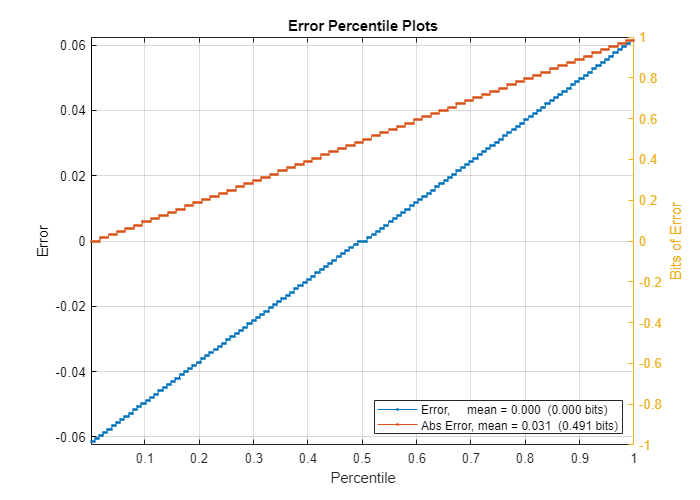

utilPlotErrorPercentile(err(ii),nty);

## Map Math in Real World Value to Operations on Stored Integers

Math in Real World Values is 

      Vy = Vu

The fixed-point scaling for each variable is 

     Vy = Sy * Qy + By

     Vu = Su * Qu + Bu

where 

      V_ are real-world values

      Q_ are stored integer vales

      S_ are scaling slopes

      B_ are scaling biases

Substituting the scaling equations into the real-world math equation gives.

SlopeU = sym('Su');
SlopeY = sym('Sy');
BiasU = sym('Bu');
BiasY = sym('By');
Qu = sym('Qu');
Qy = sym('Qy');
Vu = SlopeU * Qu + BiasU;
Vy = SlopeY * Qy + BiasY;
disp(Vy == Vu)

$$\mathrm{By}+\mathrm{Qy}\,\mathrm{Sy}=\mathrm{Bu}+\mathrm{Qu}\,\mathrm{Su}$$

Solving for the output stored integer value show the operations that must be done in code to implement the math.

Qy = expand( (Vu - BiasY) / SlopeY ) %#ok<NASGU>

$$Qy = \frac{\mathrm{Bu}}{\mathrm{Sy}}-\frac{\mathrm{By}}{\mathrm{Sy}}+\frac{\mathrm{Qu}\,\mathrm{Su}}{\mathrm{Sy}}$$

Equivalently

Qy = sym('Snet') * Qu + sym('Bnet') %#ok<NASGU>

$$Qy = \mathrm{Bnet}+\mathrm{Qu}\,\mathrm{Snet}$$

where

Snet = SlopeU / SlopeY

$$Snet = \frac{\mathrm{Su}}{\mathrm{Sy}}$$

Bnet = (BiasU - BiasY)/SlopeY

$$Bnet = \frac{\mathrm{Bu}-\mathrm{By}}{\mathrm{Sy}}$$

Keep in mind that the scaling will be constants in the real-time embedded code, so at worst, one multiplication by a constant "net Slope" and one addition by a constant "net Bias" are needed. Depending on how well the scaling of the input and output are "matched", the additive term may go away and the multiplicative term may reduce to an exact power of two. If the multiplicative term is an exact power of two, then a fast shift left or shift right can be used.

Since this case analysis is restricted to binary-point scaling, we can simplify things further.

      S_ = 2^E_

      B_ = 0

where

      E_ is the scaling fixed exponent

So for binary-point scaling, the fixed-point scaling for each variable is 

     Vy = 2^Ey * Qy

     Vu = 2^Eu * Qu

Substituting known scalings into these ideal math equation gives the following.

SlopeU = sym(2)^sym(ntu.FixedExponent);
SlopeY = sym(2)^sym(nty.FixedExponent);
Qu = sym('Qu');
Qy = sym('Qy');
Vu = SlopeU * Qu

$$Vu = \frac{\mathrm{Qu}}{1024}$$

Vy = SlopeY * Qy

$$Vy = \frac{\mathrm{Qy}}{16}$$

disp(Vy == Vu)

$$\frac{\mathrm{Qy}}{16}=\frac{\mathrm{Qu}}{1024}$$

Now solving this set of equations for Qy describes the net-scaling and conceptual level operations on the stored integers.

Vy = Vu;
Qy = expand( Vy / SlopeY )

$$Qy = \frac{\mathrm{Qu}}{64}$$

For the binary-point, a shift left or shift right is all that is needed for the ideal math.

Note, in addition to the ideal math, the implementation will need to handle overflows, rounding, and changing of container types.

## C code generation from MATLAB Coder

Let's look at the generated code needed for various combinations of overflow handling and rounding handling.

Keep an eye out of additional operations needed for rounding, usually an additive term.

Keep an  eye out for "if then else" patterns to handle saturation.

Also keep an eye on C type casts. Some of these casts will be part of the C language rule of never doing math on types smaller than an int. Some up casts may be needed to prevent overflows in intermediate results. Down casts are usually where any overflow wrapping will occur.

### Wrapping Floor

a = fi(0,ntu);
fnName = 'exFixptCastWrapFloor';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastWrapFloor.h"

int8_T exFixptCastWrapFloor(int16_T a)
{
  return (int8_T)((int32_T)a >> 6);
}


### Wrapping Nearest (Ties toward +Inf)

a = fi(0,ntu);
fnName = 'exFixptCastWrapNearTieInf';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastWrapNearTieInf.h"

int8_T exFixptCastWrapNearTieInf(int16_T a)
{
  return (int8_T)(((int32_T)a + 32) >> 6);
}


### Wrapping Round (Ties away from zero)

a = fi(0,ntu);
fnName = 'exFixptCastWrapNearTieAway';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastWrapNearTieAway.h"

int8_T exFixptCastWrapNearTieAway(int16_T a)
{
  return (int8_T)(((int32_T)a >> 6) +
                  ((((int32_T)a & 32) != 0) &&
                   ((((int32_T)a & 31) != 0) || ((int32_T)a > 0))));
}


### Wrapping Convergent (Ties to even valued)

a = fi(0,ntu);
fnName = 'exFixptCastWrapNearTieEven';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastWrapNearTieEven.h"

int8_T exFixptCastWrapNearTieEven(int16_T a)
{
  return (int8_T)((((int32_T)a >> 6) +
                   ((((int32_T)a & 32) != 0) && (((int32_T)a & 31) != 0))) +
                  ((((int32_T)a & 63) == 32) && (((int32_T)a & 64) != 0)));
}


### Wrapping Ceiling

a = fi(0,ntu);
fnName = 'exFixptCastWrapCeil';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastWrapCeil.h"

int8_T exFixptCastWrapCeil(int16_T a)
{
  return (int8_T)(((int32_T)a + 63) >> 6);
}


### Wrapping Zero

a = fi(0,ntu);
fnName = 'exFixptCastWrapZero';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastWrapZero.h"

int8_T exFixptCastWrapZero(int16_T a)
{
  int32_T i;
  if ((int32_T)a < 0) {
    i = 63;
  } else {
    i = 0;
  }
  return (int8_T)((int32_T)(int16_T)((int32_T)a + i) >> 6);
}


### Saturating Floor

a = fi(0,ntu);
fnName = 'exFixptCastSatFloor';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastSatFloor.h"

int8_T exFixptCastSatFloor(int16_T a)
{
  int16_T i;
  i = (int16_T)((int32_T)a >> 6);
  if ((int32_T)i > 127) {
    i = (int16_T)127;
  } else if ((int32_T)i < -128) {
    i = (int16_T)-128;
  }
  return (int8_T)i;
}


### Saturating Nearest (Ties toward +Inf)

a = fi(0,ntu);
fnName = 'exFixptCastSatNearTieInf';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastSatNearTieInf.h"

int8_T exFixptCastSatNearTieInf(int16_T a)
{
  int16_T i;
  i = (int16_T)(((int32_T)a + 32) >> 6);
  if ((int32_T)i > 127) {
    i = (int16_T)127;
  } else if ((int32_T)i < -128) {
    i = (int16_T)-128;
  }
  return (int8_T)i;
}


### Saturating Round (Ties away from zero)

a = fi(0,ntu);
fnName = 'exFixptCastSatNearTieAway';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastSatNearTieAway.h"

int8_T exFixptCastSatNearTieAway(int16_T a)
{
  int16_T i;
  i = (int16_T)(((int32_T)a >> 6) +
                ((((int32_T)a & 32) != 0) &&
                 ((((int32_T)a & 31) != 0) || ((int32_T)a > 0))));
  if ((int32_T)i > 127) {
    i = (int16_T)127;
  } else if ((int32_T)i < -128) {
    i = (int16_T)-128;
  }
  return (int8_T)i;
}


### Saturating Convergent (Ties to even valued)

a = fi(0,ntu);
fnName = 'exFixptCastSatNearTieEven';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastSatNearTieEven.h"

int8_T exFixptCastSatNearTieEven(int16_T a)
{
  int16_T i;
  i = (int16_T)((((int32_T)a >> 6) +
                 ((((int32_T)a & 32) != 0) && (((int32_T)a & 31) != 0))) +
                ((((int32_T)a & 63) == 32) && (((int32_T)a & 64) != 0)));
  if ((int32_T)i > 127) {
    i = (int16_T)127;
  } else if ((int32_T)i < -128) {
    i = (int16_T)-128;
  }
  return (int8_T)i;
}


### Saturating Ceiling

a = fi(0,ntu);
fnName = 'exFixptCastSatCeil';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastSatCeil.h"

int8_T exFixptCastSatCeil(int16_T a)
{
  int16_T i;
  i = (int16_T)(((int32_T)a + 63) >> 6);
  if ((int32_T)i > 127) {
    i = (int16_T)127;
  } else if ((int32_T)i < -128) {
    i = (int16_T)-128;
  }
  return (int8_T)i;
}


### Saturating Zero

a = fi(0,ntu);
fnName = 'exFixptCastSatZero';
libCfg = getMatlabCoderLibConfig();
libCfg.GenerateComments = false;
libCfg.LaunchReport = false;
codegen(fnName,'-config',libCfg,'-args',{a,coder.Constant(yLike)});

Code generation successful: View report



type(sprintf('codegen/lib/%s/%s.c',fnName,fnName))

#include "exFixptCastSatZero.h"

int8_T exFixptCastSatZero(int16_T a)
{
  int32_T i;
  int16_T i1;
  if ((int32_T)a < 0) {
    i = 63;
  } else {
    i = 0;
  }
  i1 = (int16_T)((int32_T)(int16_T)((int32_T)a + i) >> 6);
  if ((int32_T)i1 > 127) {
    i1 = (int16_T)127;
  } else if ((int32_T)i1 < -128) {
    i1 = (int16_T)-128;
  }
  return (int8_T)i1;
}


#### Copyright

Copyright 2022-2023 The MathWorks, Inc.